clear
close all
clc
opengl hardware

Der ønskes en krydsfrekvens på 3 rad/s. Dimensioner PI, så fejlen for et step går mod 0.

wc = 3

wc = 3

G_p = tf([3], [0.5 1.5 1])


G_p =
 
           3
  -------------------
  0.5 s^2 + 1.5 s + 1
 
Continuous-time transfer function.



wi = wc/4 %Regulatorfrekvensen vælges ved en fjerdedel af krydsfrekvensen

wi = 0.7500

taui = 1/wi

taui = 1.3333

Gain og fase ved krydsfrekvensen findes, så Kp kan findes.

[G_wc,P_wc] = bode(G_p,wc)

G_wc = 0.5262

P_wc = -127.8750

Kp = 1/G_wc

Kp = 1.9003

PI-regulatoren er derfor fundet

G_c = tf(1.9.*[taui 1],[taui 0])


G_c =
 
  2.533 s + 1.9
  -------------
     1.333 s
 
Continuous-time transfer function.



Det regulerede kredsløb plottes

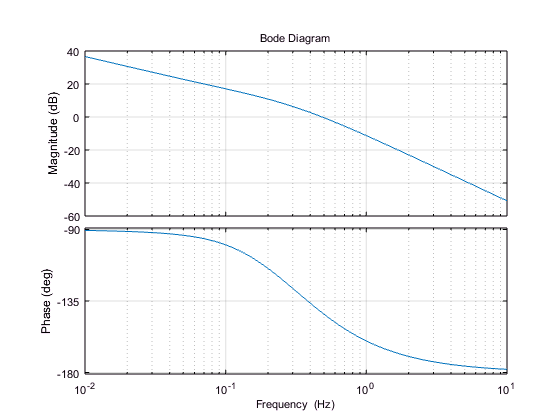

opt=bodeoptions;
opt.Grid = 'On'; opt.FreqUnits='Hz';
bode(G_c*G_p,opt)

Herefter ønskes at lave et steprespons for hele systemet, der har feedback på 1.

G_L = feedback(G_c*G_p,1)


G_L =
 
             7.6 s + 5.7
  ----------------------------------
  0.6667 s^3 + 2 s^2 + 8.933 s + 5.7
 
Continuous-time transfer function.



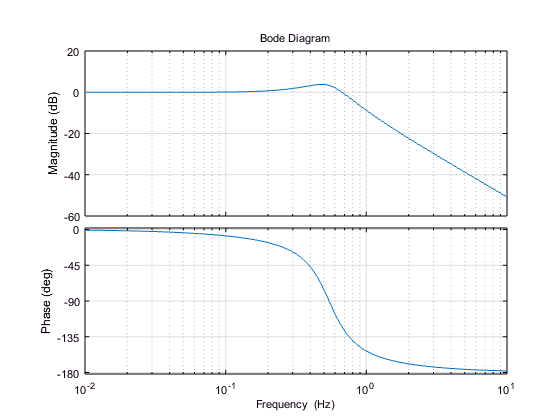

bode(G_L,opt)

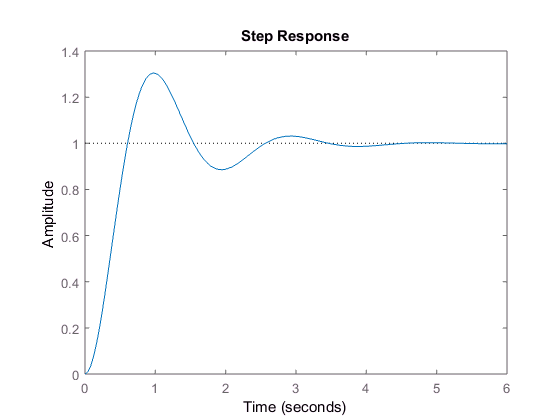

step(G_L)